clc;
clear;
close all;

## Definizione dei parametri del motore asincrono con rotore avvolto

Pn = 2100;        % Potenza nominale [kW]
Vn = 3000;        % Tensione nominale [V]
f = 50;           % Frequenza [Hz]
cosphi = 0.78;   % Fattore di potenza
p = 3;            % Numero di coppie polari
eta = 0.961;       % Rendimento
rapp_C = 2;     % Rapporto di coppia

Papp = Pn / (eta * cosphi); % Potenza apparente [kVA]

% Altri parametri
lambda = 1.85;     % Rapporto di forma
kst = 0.925;       % Coefficiente di stipamento lamierini
n_nom = 1000;          % Giri nominali [rpm]

Cu_taup3 = Papp * pi^2 / (4 * p^2 * n_nom * lambda)

Cu_taup3 = 0.4152


% Dati forniti (tau_p_cm, Cu)
tau_p_m = [10.0086, 10.5501, 11.3524, 11.9667, 13.055, 13.7613, 15.0474, 15.8612, 16.0441, 16.912, ...
            17.8268, 18.6199, 19.6272, 20.0363, 21.1199, 24.0657, 25.3675, 28.1866, 29.7114, 30.1228, ...
            31.7523, 33.9329, 35.769, 36.1814, 38.1378, 40.386, 42.5712, 44.874, 47.519, 51.383]*10^-2;

Cu = [1.7191, 1.75855, 1.80703, 1.84849, 1.91243, 1.95632, 2.0286, 2.06569, 2.07983, 2.1227, ...
      2.16645, 2.20612, 2.25159, 2.27732, 2.31895, 2.4431, 2.49346, 2.60325, 2.65691, 2.67507, ...
      2.73021, 2.79913, 2.86336, 2.88295, 2.92896, 3.00298, 3.07189, 3.1352, 3.2071, 3.30841];


% Interpolazione per ottenere più valori intermedi
tau_p_m_fine = linspace(min(tau_p_m), max(tau_p_m), 1000); % Più punti tra min e max
Cu_fine = interp1(tau_p_m, Cu, tau_p_m_fine, 'spline'); % Interpolazione con spline

% Calcoliamo i valori interpolati di Cu * tau_p_cm^3
values_fine = Cu_fine .* (tau_p_m_fine.^3);

% Troviamo il valore interpolato più vicino a Cu_taup3
[~, idx_fine] = min(abs(values_fine - Cu_taup3));

% Estrai il valore ottimale interpolato
tau_p_m_opt = tau_p_m_fine(idx_fine);
Cu_opt = Cu_fine(idx_fine);
Cu_taup3_approx = values_fine(idx_fine);

% Stampa dei risultati
fprintf('Valore ottimale interpolato di tau_p_m: %.4f\n', tau_p_m_opt);

Valore ottimale interpolato di tau_p_m: 0.5022


fprintf('Valore ottimale interpolato di Cu: %.4f\n', Cu_opt);

Valore ottimale interpolato di Cu: 3.2790


fprintf('Valore calcolato interpolato di Cu * tau_p_m^3: %.4f\n', Cu_taup3_approx);

Valore calcolato interpolato di Cu * tau_p_m^3: 0.4154


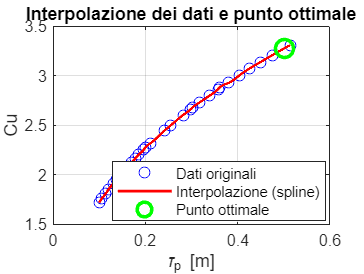


% Creazione del grafico
figure;
plot(tau_p_m, Cu, 'bo', 'MarkerSize', 6, 'DisplayName', 'Dati originali'); % Dati originali
hold on;
plot(tau_p_m_fine, Cu_fine, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Interpolazione (spline)'); % Curva interpolata
plot(tau_p_m_opt, Cu_opt, 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Punto ottimale'); % Punto ottimale
xlabel('\tau_p [m]');
ylabel('Cu');
title('Interpolazione dei dati e punto ottimale');
legend('Location', 'best');
grid on;
hold off;


% Arrotondamenti finali
tau_p_m = round(tau_p_m_opt, 3);

tau_p = tau_p_m * 1000; % mm
L0 = lambda * tau_p; % mm
D_ = (2 * p * tau_p) / pi;
D = round(D_);

Cu_check = Papp / (n_nom * (L0 * 10^(-3)) * (D * 10^(-3))^2)

Cu_check = 3.2801

## Definizione dei parametri iniziali

Lpacchetto = 90;   % Lunghezza singolo pacchetto [mm]
bcv = 6;           % Larghezza canale di ventilazione [mm]

% Calcolo del numero di canali di ventilazione radiali
ncv = round(L0 / Lpacchetto - 1);

% Calcolo della lunghezza di pacco totale
LT_ = (L0 + ncv * bcv);

% Calcolo della lunghezza di pacco netta (senza canali di ventilazione)
L0_ = LT_ - ncv * bcv;

% Ricalcolo della lunghezza del pacchetto
Lpacchetto = round(L0_ / (ncv + 1));

% L0 e LT definitivi
L0 = Lpacchetto * (ncv + 1)

L0 = 930

LT = L0 + ncv * bcv

LT = 984


% Calcolo della lunghezza di pacco effettiva (solo ferro)
Lfe = L0 * kst

Lfe = 860.2500


% Calcolo del traferro
theta = (6 * D) / (1000 * sqrt(2 * p));
theta = round(theta, 1) % Arrotondamento al decimo di mm

theta = 2.3000

% Intervallo desiderato per tau_c in mm
tau_c_min = 15;
tau_c_max = 40;

% Inizializza q
q = 1;

% Calcola tau_c e verifica la condizione
while true
    tau_c = (pi * D) / (6 * p * q);
    
    if tau_c >= tau_c_min && tau_c <= tau_c_max
        disp(['q = ', num2str(q)]);
        disp(['tau_c = ', num2str(tau_c), ' mm']);
        break; % Esci dal ciclo se la condizione è soddisfatta
    elseif tau_c < tau_c_min
        disp('Nessun valore di q trovato che soddisfa la condizione.');
        break; % Esci dal ciclo se tau_c è troppo piccolo
    end
    
    q = q + 1; % Incrementa q e riprova
end

q = 5


tau_c = 33.4754 mm



% Passo cava per il valore scelto di q
tau_c = (pi * D) / (6 * p * q);

% Calcolo del numero di cave
Z = 6 * p * q;  % Numero totale di cave
Q = 3 * q;      % Numero di cave per polo

% Raccorciamento di passo
Zracc = round(Q / 6);
r = (Q - Zracc) / Q

r = 0.8000


B_theta_m = 0.56; % Induzione media per polo [T]

% Calcolo del fattore di distribuzione
alpha = 2 * pi * p / Z;
kd1= (sin((alpha * q) / 2) / (q * sin((alpha) / 2)));

% Calcolo del fattore di raccorciamento
kr1 = sin((r * pi) / 2);

% Calcolo del fattore di avvolgimento
ka1 = kd1 * kr1;

% Calcolo del flusso per polo
Phi_prime = B_theta_m * (LT * 1e-3) * (tau_p * 1e-3); % [Wb]

% Calcolo della tensione di fase nominale
En = Vn / sqrt(3); % [V]

% Calcolo del numero di spire in serie per fase teorico
N_s_teorico = En / (0.97 * 4.44 * f * Phi_prime * ka1)

N_s_teorico = 31.9578


% Scelta del numero di spire per bobina (Nsb) e numero di circuiti in parallelo per fase (Ncp)
% L'obiettivo è avvicinarsi al valore teorico di N_s e minimizzare l'ingombro
% dell'isolamento.

% Definisci i valori di N_cp e N_sb
N_cp_values = [1, 2, 3, 6];
N_sb_values = 1:14;

% Inizializzazione della tabella
table_data = zeros(length(N_cp_values), length(N_sb_values));

% Iterazione attraverso le combinazioni di Nsb e Ncp
for i = 1:length(N_cp_values)
    for j = 3:length(N_sb_values) % Parto da N_sb >= 3 per non avere spire troppo grosse
        N_cp = N_cp_values(i);
        N_sb = N_sb_values(j);
        N_s = (Z / 3) * (N_sb / N_cp);
        table_data(i, j) = N_s;
    end
end


% Valori ottimali, molto vicino al valore N_s_teorico e minimizzo
% l'utilizzo di isolante

N_sb = 7;
N_cp = 6;

N_s = (Z / 3) * (N_sb / N_cp);

% Ricalcolo del flusso per polo
Phi = En / (0.97 * 4.44 * f * N_s * ka1);

% Calcolo dell'incremento di flusso
differenza_flusso = abs((Phi - Phi_prime) / Phi_prime) * 100;

% Ricalcolo dell'induzione media per polo al traferro
B_theta_m = Phi / (LT * 1e-3 * tau_p * 1e-3);

## Progetto della cava e della bobina di statore (piattina)

% Induzione massima nel dente
B_d_max = 1.8; % [T]
% Altezza bietta
h_b = 2.5; % [mm]
gamma_bietta = pi / 6; %[rad]
% Altezza intaglio
h_t = 1; % [mm]

% Minima larghezza del dente
w_d_min = (pi/2) * (B_theta_m * LT * tau_c) / (B_d_max * Lfe); % [mm]

% Passo cava
tau_c = (pi * D) / Z; % [mm]

% Larghezza della cava al traferro
w_c_ = tau_c - w_d_min - 2 * h_b * tan(gamma_bietta);

% Larghezza dente al traferro
w_d = tau_c - w_c_; % > w_d_min

% Verifica del rapporto tra larghezza dente e larghezza cava
rapporto_dw_p = w_d / w_c_; %(1.25 - 1.8)

% Bispessore di isolamento di conduttore
bis_cond = 0.15; % [mm]

% Bispessore di isolamento di spira
bis_sp = 0.20; % [mm]

% Bispessore di isolamento contro massa
bis_cm = 0.6 * (Vn * 10^-3 - 1); % [mm]

% Bispessore nastratura protettiva di elettrovetro
bis_ev = 0.24; % [mm]

% Bispessore del ricoprimento conduttivo in cava
bis_rc = 0; % [mm] in quanto Vn < 4kV

% Determinazione della larghezza di piattina

% Tolleranza in cava in senso orizzontale
delta_toll_h = 0.3; % [mm]

% Lasco cava-bobina in senso orizzontale
delta_lasco_h = 0.4; % [mm]

% Larghezza teorica di piattina
b_prime = w_c_ - bis_cond - bis_sp - bis_cm - bis_ev - bis_rc - delta_toll_h - delta_lasco_h;

% Numero di piattine affiancate per spira
N_ceh = 2; 

% Larghezza di piattina
b = 5.0; % [mm]

% Ridefinizione di tolleranza e lasco
delta_toll_h = 0.31; % [mm]
delta_lasco_h = 0.4; % [mm]

% Ricalcolo della larghezza di cava
w_c = N_ceh * (b + bis_cond) + bis_sp + bis_cm + bis_ev + bis_rc + delta_toll_h + delta_lasco_h;

% Ricalcolo della larghezza del dente al traferro
w_d = tau_c - w_c;
w_d_min_eff = w_d - 2 * h_b * tan(gamma_bietta);
% Ricalcolo rapporto larghezza dente/cava
rapporto_dw = w_d / w_c;

% Densità di corrente
sigma_1 = 3.5; % [A/mm^2] -> macchina di classe B

% Corrente nominale
I_n1 = Pn * 1e3 / (sqrt(3) * Vn * cosphi * eta);

% Corrente nominale di fase
I_f1 = I_n1;

% Corrente di spira
I_sp = I_f1 / N_cp;

% Sezione teorica di spira
S_sp_teorica = I_sp / sigma_1

S_sp_teorica = 25.6744


% Numero di piattine sovrapposte per spira
N_cev = 2;

% b = 5 mm -> fissato in precedenza
% Altezza singola piattina
a = 1.4; % [mm]

% Sezione netta singola piattina
S_ce = 6.78; % [mm^2]

% Sezione di spira
S_sp = S_ce * N_cev * N_ceh;

% Densità di corrente effettiva
sigma_1_eff = I_sp / S_sp;


% Tolleranza e lasco in senso verticale
delta_toll_v = 0.32; % [mm]
delta_lasco_v = 0.4; % [mm]

% Altezza di cava
h_c = 2 * (N_sb * (N_cev * (a + bis_cond) + bis_sp) + bis_cm + bis_ev + bis_rc) + h_b + h_t + delta_toll_v + delta_lasco_v;

% Rapporto altezza/larghezza di cava
rapporto_hc_wc = h_c / w_c; % 4 - 7

## Progetto giogo di statore

B_g_max = 1.3; % [T]

% Altezza del giogo
h_g = Phi / (2 * B_g_max * Lfe * 1e-3) * 1e3;

% Diametro esterno statore
D1_max = D + 2 * h_c + 2 * h_g;

% Arrotondamento al centimetro
D1_max = round(D1_max / 10) * 10;

## Progetto dell'avvolgimento di rotore

% Parametri avvolgimento rotore
q2 = q + 1;  % Numero di cave per polo per fase

Z2 = 6 * p * q2;  % Numero di cave

N2 = (2/3) * Z2;  % Numero di barre in serie per fase

Ns2 = (1/3) * Z2;  % Numero di spire equivalenti in serie per fase

% Angolo elettrico di cava
alpha2 = pi / (3 * q2);

% Coefficiente di distribuzione
kd2 = sin(q2 * alpha2 / 2) / (q2 * sin(alpha2 / 2));

% Coefficiente di avvolgimento
ka2 = kd2;

% Rapporto spire
m = (N_s * ka1) / (Ns2 * ka2);

% Tensione nominale di rotore a vuoto e rotore bloccato
E2 = En / m;

## Progetto della cava e della barra di rotore

% Diametro esterno di rotore
D2_ext = D - 2 * theta;

% Passo cava di rotore
tau_c2 = (pi * D2_ext) / Z2;

% Induzione massima nel dente
B_d2_max = 1.8; % [T]

% Larghezza dente di rotore a fondo cava
w_d2_min = (pi/2) * (B_theta_m * tau_c2 * LT) / (B_d2_max * Lfe);

% Bispessore di isolamento di conduttore
bis_cond2 = 0.15; % [mm]

% Bispessore di isolamento contro massa
bis_cm2 = 1.2; % [mm]

% Calcolo approssimativo della corrente di rotore riportata a statore
I_21 = I_f1 * cosphi;

% Calcolo approssimativo della corrente di barra
I_barra = I_21 * m;

% Densità di corrente
sigma_2 = sigma_1 * 1.1;

% Sezione della barra teorica
S_barra_p = I_barra / sigma_2;

% Sezione teorica conduttore di barra
S_cond_2 = S_barra_p / 4

S_cond_2 = 25.2643


% Tolleranza e lasco verticale
delta_toll_v2 = 0.4; % [mm]
delta_lasco_v2 = 0.3; % [mm]

% Tolleranza e lasco orizzontale
delta_toll_h2 = 0.5; % [mm]
delta_lasco_h2 = 0.4; % [mm]

% Altezza bietta di rotore
h_b2 = 3; % [mm]

% Altezza intaglio di rotore
h_t2 = 1; % [mm]

% Funzioni per larghezza cava, altezza cava e larghezza dente
f_wc2 = @(a, b) 2 * (a + bis_cond2) + bis_cm2 + delta_toll_h2 + delta_lasco_h2;
f_hc2 = @(a, b) 2 * (2 * (b + bis_cond2) + bis_cm2) + h_b2 + h_t2 + delta_toll_v2 + delta_lasco_v2;
f_wd2 = @(a, b) -(D2_ext * f_wc2(a, b) - D2_ext * tau_c2 + 2 * f_hc2(a, b) * tau_c2) / D2_ext;

% Dimensioni piattina scelte
a2 = 3.55; % [mm]
b2 = 8; % [mm]
S_ce2 = 27.8; % [mm^2]

w_d2_min

w_d2_min = 14.1701

% Calcolo larghezza dente minima, altezza cava e larghezza cava
w_d2 = f_wd2(a2, b2); % > w_d2_min -> allora si può procedere
h_c2 = f_hc2(a2, b2);
w_c2 = f_wc2(a2, b2);

h_c2 / w_c2

ans = 4.1789


% Larghezza apertura di cava al traferro
c2 = 4; % [mm]

% Ricalcolo sezione di barra
S_barra = 4 * S_ce2;

## Progetto del giogo rotorico

B_g2_max = 1.6; % [T]

% Altezza del giogo
h_g2 = Phi / (2 * B_g2_max * Lfe * 1e-3) * 1e3;

% Diametro interno massimo di rotore
D2_int_min = D2_ext - 2*h_c2 - 2*h_g2;

## Calcolo e verifica

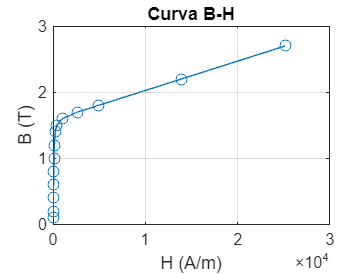

% Coefficiente di Carter per lo statore
kC1 = (tau_c / theta) / ((tau_c / theta) - ((b / theta) / (5 + b / theta)));

% Coefficiente di Carter per il rotore
kC2 = (tau_c2 / theta) / ((tau_c2 / theta) - ((b2 / theta) / (5 + b2 / theta)));

% Coefficiente di Carter complessivo
kC = kC1 * kC2;

% Coefficiente di ventilazione
kV = (1 - (ncv+1) * 2 * bcv^2 / ((LT + bcv) * (5 * theta + 2 * bcv)))^-1;

% Valore di induzione al traferro di prima armonica
B_theta_1 = (pi / 2) * B_theta_m; % [T]

% Calcolo delle amperspire al traferro
mu0 = 4 * pi * 10^-7; % Permeabilità magnetica nel vuoto
AS_theta = (B_theta_1 / mu0) * kC * kV * (theta * 10^-3); % [A]

% Larghezze del dente di statore a 1/6, 1/2 e 5/6 dell'altezza del dente
w_min_1 = w_d * ((D / 2) + (h_c / 6))/ (D / 2); % [mm]
w_med_1 = w_d * ((D / 2) + (h_c / 2))/ (D / 2); % [mm]
w_max_1 = w_d * ((D / 2) + (5 * h_c / 6))/ (D / 2); % [mm]

% Induzione nel dente alle diverse altezze
B_max_1 = B_theta_1 * (tau_c * LT) / (w_min_1 * Lfe); % [T]
B_med_1 = B_theta_1 * (tau_c * LT) / (w_med_1 * Lfe); % [T]
B_min_1 = B_theta_1 * (tau_c * LT) / (w_max_1 * Lfe); % [T]

H_ = [35, 46, 62, 72, 89, 107, 140, 240, 400, 1000, 2650, 4900, 13900, 25150]; % [A/m]
B = [0.1, 0.2, 0.4, 0.6, 0.8, 1, 1.2, 1.4, 1.5, 1.6, 1.7, 1.8, 2.2, 2.7]; % [T]

% Plotting della curva B-H
plot(H_, B, '-o');
xlabel('H (A/m)');
ylabel('B (T)');
title('Curva B-H');
grid on;

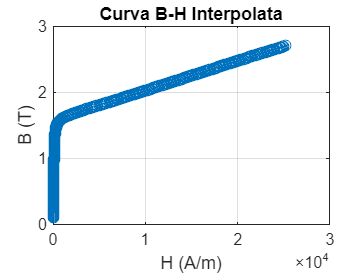


% Calcolo dell'interpolante cubica della curva H-B:
vs = spline(B, H_); 
y = @(x) ppval(vs, x);

% Generazione di punti per la curva interpolata
B_interp = linspace(min(B), max(B), 500);
H_interp = y(B_interp);

% Plotting della curva interpolata
plot(H_interp, B_interp, '-o');
xlabel('H (A/m)');
ylabel('B (T)');
title('Curva B-H Interpolata');
grid on;


% Calcolo del campo magnetico H corrispondente alle varie induzioni nel dente
H_max_1 = y(B_max_1); % [A/m]
H_med_1 = y(B_med_1); % [A/m]
H_min_1 = y(B_min_1); % [A/m]

% Ampere-spire nei denti di statore
AS_d1 = (H_max_1 + H_med_1 + H_min_1) * (h_c * 10^-3) / 3; % [A]
% Altezza della cava a meno di bietta e intaglio
h_c_prime = h_c2 - h_b2 - h_t2; % [mm]

% Ampere-spire nei denti di rotore
% Larghezza del dente di rotore alle diverse altezze
w_min_2 = w_d2; % [mm]
w_med_2 = w_min_2 * ((D2_ext / 2) - (h_c2 / 2) + (h_c_prime / 2)) / (D2_ext / 2 - h_c2); % [mm]
w_max_2 = w_min_2 * ((D2_ext / 2) - (h_c2 / 2) + h_c_prime) / (D2_ext / 2 - h_c2); % [mm]

% Induzione nel dente di rotore alle diverse altezze
B_max_2 = B_theta_1 * (tau_c2 * LT) / (w_min_2 * Lfe); % [T]
B_med_2 = B_theta_1 * (tau_c2 * LT) / (w_med_2 * Lfe); % [T]
B_min_2 = B_theta_1 * (tau_c2 * LT) / (w_max_2 * Lfe); % [T]

% Calcolo del campo magnetico H alle varie altezze nel dente di rotore
H_max_2 = y(B_max_2); % [A/m]
H_med_2 = y(B_med_2); % [A/m]
H_min_2 = y(B_min_2); % [A/m]

% Ampere-spire nei denti di rotore
AS_d2 = (H_max_2 + H_med_2 + H_min_2) * (h_c2 * 10^-3) / 3; % [A]

% Ampere-spire nel giogo di statore
% Induzione e campo magnetico nel giogo di rotore
B_g1 = 0.85 * Phi / (2 * h_g * Lfe) * 10^6; % [T]
H_g1 = y(B_g1); % [A/m]
% Lunghezza azimutale del giogo di rotore
L_g = pi * (D + 2 * h_c + h_g) / (2 * p); % [mm]
% Calcolo Amperespire
AS_g1 = H_g1 * L_g * 10^-3; % [A]

% Ampere-spire nel giogo di rotore
% Induzione e campo magnetico nel giogo di rotore
B_g2 = 0.85 * Phi / (2 * h_g2 * Lfe) * 10^6; % [T]
H_g2 = y(B_g2); % [A/m]
% Lunghezza azimutale del giogo di rotore
L_g2 = pi * (D2_ext - 2 * h_c2 - h_g2) / (2 * p); % [mm]
% Calcolo Amperespire
AS_g2 = H_g2 * L_g2 * 10^-3; % [A]

% Calcolo della corrente magnetizzante
AS_mu = AS_theta + AS_d1 + AS_d2 + (1/2 * AS_g1) + (1/2 * AS_g2); % [A]
AS_percentuali_su_theta = (AS_theta / AS_mu) * 100;
% Corrente di magnetizzazione
I_mu = (pi * AS_mu * p) / (3 * sqrt(2) * N_s * ka1); % [A]
i_mu_percent_I_n1 = (I_mu / I_f1) * 100;

## Calcolo delle resistenze

% Resistenza di fase di statore

% Sporto del tratto rettilineo dal pacco (esclusa piastra)
delta_3 = 0.6 * (Vn / sqrt(3))^(0.541); % [mm]

% Distanza minima tra tratti obliqui della testata
d_min = 2.4 + (4.5 * 10^-4 * Vn / sqrt(3)); % [mm]

w_med_1;

% Definisco d come segue
d = w_med_1 / 2; % [mm] > d_min

% Altezza della bobina
delta_1 = (h_c - h_b - h_t) / 2; % [mm]

% Angolo di inclinazione del tratto obliquo
alpha_m = acos(d / tau_c); % [rad]

% Passo di bobina
tau_b = (pi * (D + h_c) * r) / (2 * p); % [mm]

% Lunghezza obliquo di testata di statore
delta_obl = tau_b / (2 * sqrt(1 - (d / tau_c)^2)); % [mm]

% Spessore piastra di pressione
delta_piastra = 15; % [mm]

% Lunghezza totale testa di avvolgimento
L_test = 2 * delta_piastra + 2 * delta_3 + 2 * delta_obl + 2 * delta_1; % [mm]

% Lunghezza media spira
L_sm = 2 * LT + 2 * L_test; % [mm]

% Resistività del rame a 75°C
rho_Cu = 0.01784 * (1 + (0.00381 * (75 - 20))); % [Ohm*mm^2/m]

% Resistenza CC di fase
R_1cc = rho_Cu * (L_sm * 10^-3) * N_s / (S_sp * N_cp); % [Ohm]

% Coefficiente di effetto pelle
xi = a * sqrt((2 * pi * f * mu0 * N_ceh * b) / (2 * rho_Cu * w_c)); % [-]

% Numero dconduttori sovrapposti per cava
m_prime = 2 * N_sb * N_cev * N_ceh; % [-]

% Coefficiente di effetto pelle
k_r_fe = 1 + (((m_prime^2 - 0.2) * xi^4) / 9); % [-]

% Rapporto lunghezze testa/conduttore
lambda_prime = (L_sm - (2 * L0)) / (2 * L0); % [-]

% Coefficiente di effetto pelle
k_r = 1 + ((m_prime^2 - 1) / (9 * (lambda_prime + 1)) * xi^4); % [-]

% Resistenza AC di fase
R_1ca = R_1cc * k_r; % [Ohm]

% Resistenza di fase di rotore

% Sporto del tratto rettilineo dal pacco (esclusa piastra)
delta_3r = 0.6 * (E2)^(0.541); % [mm]

% Distanza minima tra tratti obliqui della testata
d_min_2 = 2.4 + (4.5 * 10^-4 * E2); % [mm]

w_med_2;

% Definisco d come segue
d_2 = w_med_2 / 2; % [mm] > d_min_2

% Altezza della barra
delta_1r = (h_c2 - h_b2 - h_t2) / 2; % [mm]

% Angolo inclinazione testata avvolgimento rotore
alpha_m2 = acos(d_2 / tau_c2); % [rad]

% Passo di 'bobina' (avvolgimento ondulato)
tau_b2 = (pi * (D2_ext - h_c2)) / (2 * p); % [mm]

% Lunghezza obliquo di testata di rotore
delta_obl2 = tau_b2 / (2 * sqrt(1 - (d_2 / tau_c2)^2)); % [mm]

% Lunghezza totale testa di avvolgimento rotore
L_test2 = 2 * delta_piastra + 2 * delta_3r + 2 * delta_obl2 + 2 * delta_1r; % [mm]

% Lunghezza media spira rotore
L_sm2 = 2 * LT + 2 * L_test2; % [mm]

% Resistenza di fase rotore
R_2 = rho_Cu * (L_sm2 * 10^-3) * Ns2 / S_barra; % [Ohm]

% Resistenza di fase rotore riferita allo statore
R_21 = R_2 * m^2; % [Ohm]

## Calcolo delle reattanze

% Reattanza principale satura
X_p = (6 * f * N_s^2 * ka1^2 * Phi) / (AS_mu * p) % [Ohm]

X_p = 14.9112


Vn / (sqrt(3) * I_mu * 0.97)

ans = 14.9015


% Reattanza principale non satura
X_pu = (6 * f * N_s^2 * ka1^2 * Phi) / (AS_theta * p); % [Ohm]

% Reattanza di dispersione in cava dello statore
% Definizione delle variabili
r;  % Raccorciamento di passo in per unit del passo polare

% Formula per il coefficiente di riduzione della permeanza di cava nella zona conduttrice
kCu = @(r) (3 * r - 2) + (3 * (1 - r) * 13 / 16);

% Formula per il coefficiente di riduzione della permeanza di cava nella zona in aria
karia = @(r) (3 * r - 2) + (3 * (1 - r) * 3 / 4);

% Calcolo dei coefficienti
kCu1 = kCu(r);
karia1 = karia(r);

h1 = h_c - h_t - h_b - 2 * bis_cm;  % Altezza delle bobine a meno dell'isolamento contro massa (mm)
h2 = bis_cm / 2 + h_b + h_t;       % Altezza di cava in aria sopra le parti conduttive delle bobine (mm)
h5 = bis_cm;                     % Distanza tra le parti conduttive delle bobine (mm)

% Permeanza di cava
lambda_c = (h1 / (3 * w_c) * kCu1) + (h2 / (w_c * ka1)) + (h5 / (4 * w_c));

% Induttanza di dispersione in cava
Lc = 2 * mu0 * L0 * 10^-3 * (N_s^2 / (p * q)) * lambda_c; % (H)

% Reattanza di dispersione di cava
Xc = 2 * pi * f * Lc;

h1r = h_c2 - h_t2 - h_b2 - 2 * bis_cm2;  % Altezza delle barre a meno dell_isolamento contro massa (mm)
h2r = bis_cm2 / 2;                    % Altezza di cava in aria sopra le barre (mm)
h3r = h_b2;                            % Altezza della bietta (mm)
h4r = h_t2;                            % Altezza dell_intaglio (mm)
h5r = bis_cm2;                        % Distanza tra le parti conduttive delle barre (mm)

% Coefficienti di riduzione della permeanza di cava nel rotore
kCu2 = kCu(1);    % Coefficiente di riduzione nella zona conduttrice
karia2 = kCu(1);  % Coefficiente di riduzione nella zona in aria

% Permeanza di cava nel rotore
lambda_c2 = (h1r / (3 * w_c2) * kCu2) + ((h2r / w_c2) + (h3r / (w_c2 - c2) * log(w_c2 / c2)) + (h4r / c2)) * karia2 + (h5r / (4 * w_c2));

% Induttanza di dispersione in cava del rotore
Lc2 = 2 * mu0 * L0 * 1e-3 * (Ns2^2 / (p * q2)) * lambda_c2;

% Reattanza di dispersione in cava del rotore
Xc2 = 2 * pi * f * Lc2;

% Reattanza di dispersione in cava riportata a statore
Xc21 = Xc2 * m^2;


% Reattanza di dispersione in testata per una fase di statore
% Calcolo dell'ingombro assiale della parte obliqua
delta_2 = (tau_b / (2 * tan(alpha_m)));

% Permeanza di testata
lambda_t = 1.2 * ka1^2 * ((delta_3 / LT) + (delta_2 / (2 * LT)));

% Induttanza di dispersione in testata
Lt = 8 * mu0 * (N_s^2 / p) * LT * 10^-3 * lambda_t;

% Reattanza di dispersione in testata
Xt = 2 * pi * f * Lt;

% Reattanza di dispersione in testata per una fase di rotore
% Calcolo dell'ingombro assiale della parte obliqua
delta_2r = (tau_b2 / (2 * tan(alpha_m2)));

% Permeanza di testata
lambda_t2 = 1.2 * ka2^2 * ((delta_3r / LT) + (delta_2r / (2 * LT)));

% Induttanza di dispersione in testata
Lt2 = 8 * mu0 * (Ns2^2 / p) * LT * 10^-3 * lambda_t2;

% Reattanza di dispersione in testata
Xt2 = 2 * pi * f * Lt2;

% Reattanza di dispersione in testata riportata allo statore
Xt21 = Xt2 * m^2;

% Reattanza di dispersione al traferro per una fase di statore
% Definizione delle variabili
alpha = 2 * pi * p / Z;
n_max = 100;  % Numero massimo di armoniche considerate

% Fattore di distribuzione relativo all'armonica h
kdh = @(h) (sin((alpha .* h * q) / 2) ./ (q * sin((alpha .* h) / 2)));

% Fattore di raccorciamento relativo all'armonica h
krh = @(h) sin((r * pi .* h) / 2);

% Fattore di avvolgimento relativo all'armonica h
kah = @(h) kdh(h) .* krh(h);

% Coefficiente di riduzione della reattanza principale
%sigma_theta = @(n) sum((kah(n) ./ (kah(1) .* n.^2)).^2, 'all');

% Coefficiente di riduzione della reattanza principale
sigma_theta = @(n) sum((kah(n) ./ (kah(1) .* n)).^2, 'all');


n = generaArray6n(1 : n_max);
% Calcolo del valore limite del coefficiente di riduzione
sigma_theta_lim = sigma_theta(n);

% Calcolo della reattanza di dispersione al traferro
X_theta = X_pu * sigma_theta_lim;

% Definizione delle variabili
alpha2 = 2 * pi * p / Z2;

% Fattore di distribuzione relativo all'armonica h
kdh2 = @(h) (sin((alpha2 .* h * q) / 2) ./ (q * sin((alpha2 .* h) / 2)));

% Fattore di raccorciamento relativo all'armonica h
krh2 = @(h) sin((pi .* h) / 2);

% Fattore di avvolgimento relativo all'armonica h
kah2 = @(h) kdh2(h) .* krh2(h);

% Coefficiente di riduzione della reattanza principale
%sigma_theta2 = @(n) sum((kah2(n) ./ (kah2(1) .* n.^2)).^2, 'all');

% Coefficiente di riduzione della reattanza principale
sigma_theta2 = @(n) sum((kah2(n) ./ (kah2(1) .* n)).^2, 'all');

% Calcolo del valore limite del coefficiente di riduzione
sigma_theta_lim2 = sigma_theta2(n);

% Calcolo della reattanza di dispersione al traferro
X_theta21 = X_pu * sigma_theta_lim2;

% Calcolo del punto di lavoro nominale
% Definizione delle variabili
i = 1i;         % Unità immaginaria

% Resistenze e reattanze
R1 = R_1ca;      % Resistenza di statore (Ω)
X1 = Xc + Xt + X_theta;  % Reattanza totale di statore (Ω)
R2 = R_21;       % Resistenza di rotore riportata a statore (Ω)
X21 = Xc21 + Xt21 + X_theta21;  % Reattanza totale di rotore riportata a statore (Ω)
Xp = X_p;      % Reattanza principale saturata (Ω)

% Impedenza longitudinale di statore
Z1_prime = R1 + i * X1;

% Impedenza longitudinale di rotore in funzione dello scorrimento
Z2_prime = @(s) (R2 ./ s) + i * X21;

% Impedenza trasversale
Zp_prime = i * Xp;

% Impedenza equivalente vista dallo statore
Zeq = @(s) Z1_prime + (Z2_prime(s) .* Zp_prime) ./ (Z2_prime(s) + Zp_prime);

% Corrente di statore in funzione dello scorrimento
I1_prime = @(s) (Vn / sqrt(3)) ./ Zeq(s);

% Fattore di potenza in funzione dello scorrimento
cos_phi = @(s) cos(angle(Zeq(s)));

% Corrente di rotore riportata a statore
I21_prime = @(s) I1_prime(s) .* (Zp_prime ./ (Zp_prime + Z2_prime(s)));

% Potenza all'asse in funzione dello scorrimento
Passe = @(s) 3 * R2 * ((1 - s) ./ s) .* (abs(I21_prime(s)).^2) * 10^-3; % in kW

% Velocità di rotazione in funzione dello scorrimento
omega_m = @(s) (2 * pi * f .* (1 - s)) / p ;

% Coppia all'asse in funzione dello scorrimento
Casse = @(s) Passe(s) * 10^3 ./ omega_m(s);

Casse_s = @(s) (p ./ (2 * pi * f .* s)) .* (Vn^2 * R2) ./ ((X1 + X21)^2 + (R1 + R2./s).^2);
s_max = R2 / sqrt(R1^2 + (X1 + X21)^2);
CMAX_s = Casse_s(s_max)

CMAX_s = 7.0341e+04



% Funzione da azzerare: Passe(s) - Pn = 0
fun = @(s) Passe(s) - Pn;

% Troviamo s_n risolvendo l'equazione
s_n = fzero(fun, 0.001); % Valore iniziale vicino allo 0

% Coppia nominale
Cn = Casse(s_n);

% Coppia massima
Casse_neg = @(s) -1 * Casse(s);
[s_max, C_MAX_neg] = fminbnd(Casse_neg, 0.001, 0.5); % Trova il massimo nell'intervallo [0, 5]
CMAX = -1 * C_MAX_neg;

rapporto_C = CMAX / Cn;
rapporto_C_s = CMAX_s / Cn

rapporto_C_s = 3.4907


% Fattore di potenza nominale
cos_phi_n = cos_phi(s_n) 

cos_phi_n = 0.9203

cosphi

cosphi = 0.7800

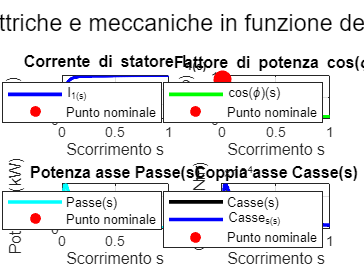

% Definizione dell'intervallo di scorrimento
s = linspace(0, 1, 1000);  % Scorrimento da 0 a 1 con 1000 punti

% Calcolo delle grandezze per ogni valore di scorrimento
I1_vals = abs(I1_prime(s));         % Corrente di statore
cos_phi_vals = cos_phi(s);          % Fattore di potenza
Passe_vals = Passe(s);              % Potenza all'asse in kW
Casse_vals = Casse(s);              % Coppia all'asse in Nm
Casse_s_vals = Casse_s(s);

% Creazione di una finestra con 4 sottografi
figure;

% 1. Corrente di statore
subplot(2,2,1);
plot(s, I1_vals, 'b', 'LineWidth', 2);
hold on;
scatter(s_n, abs(I1_prime(s_n)), 100, 'r', 'filled'); % Punto nominale
grid on;
xlabel('Scorrimento s');
ylabel('I_1 (A)');
title('Corrente di statore I_1(s)');
legend('I_1(s)', 'Punto nominale');

% 2. Fattore di potenza
subplot(2,2,2);
plot(s, cos_phi_vals, 'g', 'LineWidth', 2);
hold on;
scatter(s_n, cos_phi(s_n), 100, 'r', 'filled'); % Punto nominale
grid on;
xlabel('Scorrimento s');
ylabel('cos(\phi)');
title('Fattore di potenza cos(\phi)');
legend('cos(\phi)(s)', 'Punto nominale');

% 3. Potenza all'asse
subplot(2,2,3);
plot(s, Passe_vals, 'c', 'LineWidth', 2);
hold on;
scatter(s_n, Passe(s_n), 100, 'r', 'filled'); % Punto nominale
grid on;
xlabel('Scorrimento s');
ylabel('Potenza (kW)');
title('Potenza asse Passe(s)');
legend('Passe(s)', 'Punto nominale');

% 4. Coppia all'asse
subplot(2,2,4);
plot(s, Casse_vals, 'k', 'LineWidth', 2);
hold on;
plot(s, Casse_s_vals, 'b', 'LineWidth', 2);
hold on;
scatter(s_n, Casse(s_n), 100, 'r', 'filled'); % Punto nominale
grid on;
xlabel('Scorrimento s');
ylabel('Coppia (Nm)');
title('Coppia asse Casse(s)');
legend('Casse(s)', 'Casse_s(s)', 'Punto nominale');

% Adattare la visualizzazione
sgtitle('Grandezze elettriche e meccaniche in funzione dello scorrimento');
hold off;

% -------------------------------------
% Perdite Joule nello statore
% -------------------------------------
PCu1 = 3 * R1 * abs(I1_prime(s_n))^2 * 1e-3; % Perdite Joule statore in kW

% -------------------------------------
% Perdite Joule nel rotore
% -------------------------------------
PCu2 = 3 * R_21 * abs(I21_prime(s_n))^2 * 1e-3; % Perdite Joule rotore in kW

% -------------------------------------
% Perdite nel ferro
% -------------------------------------
gamma_fe = 7.6; % Densità del ferro (kg/dm^3)

% Peso dei denti di statore
Gd1 = (pi * ((D + 2 * h_c)^2 - D^2) / 4 - Z * w_c * h_c) * 1e-4 * Lfe * 1e-2 * gamma_fe;
% Peso del giogo di statore
Gg1 = (pi * (D1_max^2 - (D + 2 * h_c)^2) / 4) * 1e-4 * Lfe * 1e-2 * gamma_fe;

% Cifra di perdita specifica e coefficiente di lavorazione
Cp = 1.7; % W/kg
kL = 1.25;

% Perdite nel ferro
Pfe = (Cp * (B_max_1^2 * Gd1 + B_g1^2 * Gg1) * kL) * 1e-3; % kW

% -------------------------------------
% Perdite meccaniche
% -------------------------------------
Pattr = 17 * 1400 * (D * 1e-3)^2 * (LT * 1e-3) * 1e-3; % kW

% Sovratemperatura media e coefficiente di scambio termico
delta_Ta = 17; % °C
ca = 1210; % W/(°C * m^3)

% Portata d'aria richiesta
Q = (PCu1 + PCu2 + Pfe + Pattr) * 1e3 / (ca * delta_Ta); % m^3/s

% Diametro del ventilatore
Dv = D + 2 * h_c; % mm

% Prevalenza richiesta
H = 8 * (Q^2) / (Dv * 1e-3)^4; % m

% Densità dell'aria e gravità
gamma_a = 1.23; % kg/m^3
g = 9.81; % m/s^2

% Rendimento del ventilatore
eta_v = 0.6;

% Potenza ventilatore
Pvent = ((Q * gamma_a * g * H) / (eta_v)) * 1e-3; % kW

% Perdite meccaniche totali
Pmec = Pattr + Pvent; % kW

% -------------------------------------
% Perdite addizionali
% -------------------------------------
Padd = 5 / 1000 * Pn; % kW

% -------------------------------------
% Perdite totali e rendimento
% -------------------------------------
Ptot = PCu1 + PCu2 + Pfe + Pmec + Padd; % kW
eta_calc = 1 - (Ptot / Pn) % Rendimento

eta_calc = 0.9698

eta

eta = 0.9610

function arrotondato = arrotonda_al_multiplo_di_5(numero)
  arrotondato = round(numero / 5) * 5;
end

function risultato = generaArray6n(n_values)
  % n_values: vettore di valori di n
  % risultato: array contenente 6*n - 1 e 6*n + 1 per ogni n

  risultato = []; % Inizializza l'array risultato

for n = n_values
    risultato = [risultato, 6*n - 1, 6*n + 1]; % Aggiunge i valori all'array
  end
end